### **Load Preprocessed dataset**

% 경로지정
path = fileparts(which('train_net.mlx'));
addpath(genpath(path));

% 데이터세트 전처리
data = load("dataset\NYUv2_dataset_384.mat");
dataset_RGB = data.dataset_RGB;
dataset_DEP = data.dataset_DEP;
clear data;

% split train valid dataset
train_RGB = dataset_RGB(1:1200,:,:,:);
train_DEP = dataset_DEP(1:1200,:,:);

valid_RGB = dataset_RGB(1201:1449,:,:,:);
valid_DEP = dataset_DEP(1201:1449,:,:);

clear dataset_RGB dataset_DEP

% Save dataset in datastore
train_dsX_RGB = arrayDatastore(permute(train_RGB,[2,3,4,1]),IterationDimension=4);
train_dsY_DEP = arrayDatastore(permute(train_DEP,[2,3,1]),IterationDimension=3);
clear train_RGB train_DEP

valid_dsX_RGB = arrayDatastore(permute(valid_RGB,[2,3,4,1]),IterationDimension=4);
valid_dsY_DEP = arrayDatastore(permute(valid_DEP,[2,3,1]),IterationDimension=3);
clear valid_RGB valid_DEP

% combine dataset for training
dsTrain = combine(train_dsX_RGB,train_dsY_DEP);
dsValid = combine(valid_dsX_RGB, valid_dsY_DEP);
dsOut = read(dsTrain) % 1: RGB   2: Depth

clear train_dsX_RGB train_dsY_DEP valid_dsX_RGB valid_dsY_DEP

### Prepare network for train

Load designed network with pretrained backbone learnables

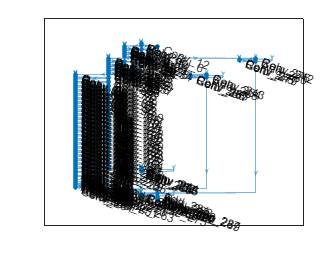

run('net_MDE.mlx');

% check layergraph and add output layer at the end of the network  
lgraph = net.layerGraph;
lgraph = addLayers(lgraph,regressionLayer('Name','regression'));
lgraph = connectLayers(lgraph,'Relu_293','regression');

% Train the network using Deep Network Designer.
deepNetworkDesigner(lgraph);

### Save trained model

outputDir = path+"\model\net_MDE";
outputFile = fullfile(outputDir, "net_trained.mat");
save(outputFile, "net");